Disable MATLAB Copilot in settings to hide "Explain Error" buttons
EEGLAB Warning: Invalid argument 'noui'. Restarting EEGLAB interface instead.
Some menu items hidden. Use Preference menu to show them all.
eeglab: options file is ~/eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Fileio" v260210 to the path
EEGLAB: adding "ICLabel" v1.7 (see >> help eegplugin_iclabel)
EEGLAB: adding "SIFT" v1.6 (see >> help eegplugin_sift)
EEGLAB: adding "bva-io" v1.74 (see >> help eegplugin_bva_io) - new version 1.75 available
EEGLAB: adding "clean_rawdata" v2.11 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v5.6 (see >> help eegplugin_dipfit)
EEGLAB: adding "firfilt" v2.8 (see >> help eegplugin_firfilt)
Disable MATLAB Copilot in settings to hide "Explain Error" buttons


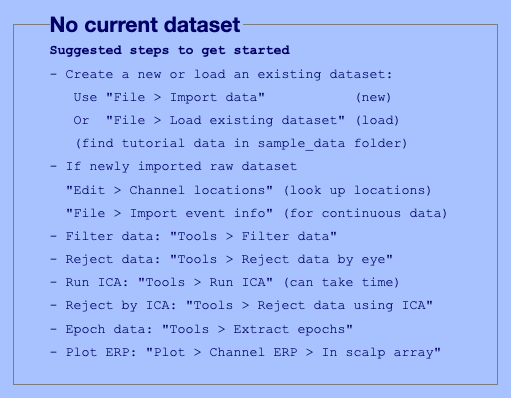

%% ========================================================================
% EEG PREPROCESSING PIPELINE PER BLOC
% ========================================================================
% Description:
% This script pre-processes raw EEG data (BrainVision format) per bloc 
% (Encoding, Gap, Old/New, 2AFC) based on markers. It includes visual and 
% automatic artifact rejection (ASR), ICA with ICLabel, interpolation, 
% and epoching based on behavioral data from a CSV file.
%
% Dependencies & Plugins required:
%   - EEGLAB (tested on 2025 version)
%   - bva-io (BrainVision import)
%   - clean_rawdata (ASR)
%   - ICLabel
%
% Manual steps during execution:
%   - Visual rejection of noisy channels per bloc (pop_eegplot will pause).
%
% Expected CSV Format for behavioral data (columns required):
%   - Object_Encode, Condition_Encode, Scene
%   - key_AFC.corr, Correct_key_AFC, key_AFC.keys
%   - key_item.corr, OldNew_Condition, Correct_Key_Old, key_item.keys
% ========================================================================

clear all; close all; clc;

%% ------------------------------------------------------------------------
% 0. CONFIGURATION (Only modify variables in this section)
% ------------------------------------------------------------------------
% Use relative paths if the script is in the project folder, or absolute paths.
eeglab_path = '/Users/meissane/Downloads/eeglab2025.1.0/'; % Path to EEGLAB
%input_dir   = './SEED_EEG_data_ia/'; % Path to raw data (vhdr, vmrk, csv)
%output_dir  = './SEED_EEG_data_ds/'; % Path to save preprocessed data
input_dir = '/Users/meissane/Documents/ECM/SSE/Code/SEED_EEG_data_ia/';
output_dir = '/Users/meissane/Documents/ECM/SSE/Code/SEED_EEG_data_ia/';


subject         = 'IA3006'; % Subject ID
fichier_vhdr    = [subject '.vhdr'];
fichier_markers = [subject '.vmrk'];
csv_file        = [subject '.csv'];

%% ------------------------------------------------------------------------
% 1. INITIALIZATION & DATA LOADING

restoredefaultpath; % Avoid path conflicts
addpath(eeglab_path); 
[ALLEEG, EEG, CURRENTSET] = eeglab('noui'); % Launch EEGLAB without GUI


% Create output directory if it doesn't exist
if ~exist(output_dir, 'dir')
    mkdir(output_dir);
end

% File existence checks
vhdr_path = fullfile(input_dir, fichier_vhdr);
if ~isfile(vhdr_path)
    error('Raw EEG file not found: %s\nPlease check input_dir and subject ID.', vhdr_path);
end

% Load raw data
EEG = pop_loadbv(input_dir, fichier_vhdr); 

pop_loadbv(): reading header file
Done.
pop_loadbv(): reading EEG data
pop_loadbv(): scaling EEG data
pop_loadbv(): reading marker file
Done.


EEG = pop_chanedit(EEG, 'lookup', 'standard_1005.elc'); % Set electrode coordinates

readlocs(): 'elc' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240 250 260 270 280 290 300 310 320 330 340 350 360 370 380 390 400 410 420 430 440 450 460 470 480 490 500 510 520 530 540 550 560 570 580 590 600 610 620 630 640 650 660 670 680 690 700 702
63 channel with the same label found and imported
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs



%% ------------------------------------------------------------------------
% 2. VISUALIZATION OF RAW SIGNAL

% pop_eegplot(EEG, 1, 1, 1); % Uncomment if you want to inspect raw data initially

%% ------------------------------------------------------------------------
% 3. SLICING OF THE SIGNAL INTO BLOCS

% Encoding  -> 'Stim'     and 'Rating'
% Old/New   -> 'Item'     and 'Resp_Item'
% AFC       -> 'AFC'      and 'Resp_Asso'
% Gap       -> Between Encoding and Old/New

buffer = 2 * EEG.srate; % 2 seconds margin before/after each bloc

% Retrieve all latency info by type
if isempty(EEG.event)
    error('No markers found in the dataset. Please check the .vmrk file.');
end

types = {EEG.event.type};
lats  = [EEG.event.latency];

enc_lats  = lats(strcmp(types, 'Stim') | strcmp(types, 'Rating'));
item_lats = lats(strcmp(types, 'Item') | strcmp(types, 'Resp_Item'));
afc_lats  = lats(strcmp(types, 'AFC')  | strcmp(types, 'Resp_Asso'));

if isempty(enc_lats) || isempty(item_lats) || isempty(afc_lats)
    warning('One or more marker types are missing. Slicing might fail.');
end

% Boundaries of each bloc
enc_start  = max(1, min(enc_lats) - buffer);
enc_end    = min(EEG.pnts, max(enc_lats) + buffer);

item_start = max(1, min(item_lats) - buffer);
item_end   = min(EEG.pnts, max(item_lats) + buffer);

afc_start  = max(1, min(afc_lats) - buffer);
afc_end    = min(EEG.pnts, max(afc_lats) + buffer);

% Gap
gap_start  = enc_end + 1;
gap_end    = item_start - 1;

% Boundaries verification
fprintf('\n--- Boundaries of each bloc ---\n');


--- Boundaries of each bloc ---


fprintf('Encoding  : %.1f s -> %.1f s\n', enc_start/EEG.srate,  enc_end/EEG.srate);

Encoding  : 295.0 s -> 762.8 s


fprintf('Gap       : %.1f s -> %.1f s\n', gap_start/EEG.srate,  gap_end/EEG.srate);

Gap       : 762.8 s -> 1985.4 s


fprintf('Old/New   : %.1f s -> %.1f s\n', item_start/EEG.srate, item_end/EEG.srate);

Old/New   : 1985.4 s -> 2507.2 s


fprintf('AFC       : %.1f s -> %.1f s\n', afc_start/EEG.srate,  afc_end/EEG.srate);

AFC       : 2579.2 s -> 2926.7 s



% Slicing with pop_select
EEG_enc  = pop_select(EEG, 'point', [enc_start  enc_end]);

eeg_insertbound(): 2 boundary (break) events added.
eeg_checkset note: event field format 'visible' made uniform
eeg_checkset note: event field format 'code' made uniform
eeg_checkset note: events' order (re)sorted by time
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
eeg_checkset note: events' order (re)sorted by time


EEG_gap  = pop_select(EEG, 'point', [gap_start  gap_end]);

eeg_insertbound(): 2 boundary (break) events added.
eeg_checkset note: event field format 'visible' made uniform
eeg_checkset note: event field format 'code' made uniform
eeg_checkset note: events' order (re)sorted by time
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
eeg_checkset note: events' order (re)sorted by time


EEG_item = pop_select(EEG, 'point', [item_start item_end]);

eeg_insertbound(): 2 boundary (break) events added.
eeg_checkset note: event field format 'visible' made uniform
eeg_checkset note: event field format 'code' made uniform
eeg_checkset note: events' order (re)sorted by time
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
eeg_checkset note: events' order (re)sorted by time


EEG_afc  = pop_select(EEG, 'point', [afc_start  afc_end]);

eeg_insertbound(): 2 boundary (break) events added.
eeg_checkset note: event field format 'visible' made uniform
eeg_checkset note: event field format 'code' made uniform
eeg_checkset note: events' order (re)sorted by time
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
eeg_checkset note: events' order (re)sorted by time



% Summary of markers per bloc
fprintf('\n--- Markers per bloc info ---\n');


--- Markers per bloc info ---


for blk = {{'Encoding', EEG_enc}, {'Gap', EEG_gap}, {'Old/New',  EEG_item}, {'AFC', EEG_afc}}
    name   = blk{1}{1};
    EEGtmp = blk{1}{2};
    if ~isempty(EEGtmp.event)
        utypes = unique({EEGtmp.event.type});
        fprintf('%-10s : %d events | types : %s\n', name, length(EEGtmp.event), strjoin(utypes, ', '));
    else
        fprintf('%-10s : 0 events\n', name);
    end
end

Encoding   : 122 events | types : Rating, Stim, boundary
Gap        : 3 events | types : boundary
Old/New    : 182 events | types : Item, Resp_Item, boundary
AFC        : 121 events | types : AFC, Resp_Asso, boundary



%% ------------------------------------------------------------------------
% 4. VISUAL REJECTION OF NOISY CHANNELS

% Goal: Prevent ASR from being too aggressive by removing extremely bad channels manually.

% --- ENCODING ---
EEG_enc_initial = EEG_enc; % Save original structure for final interpolation
EEG_enc_temp = EEG_enc; % Temporary filtered/rereferenced EEG for visual inspection
EEG_enc_temp = pop_eegfiltnew(EEG_enc_temp, 'locutoff', 1, 'hicutoff', 45);

pop_eegfiltnew() - performing 1651 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 45] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 45.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


EEG_enc_temp = pop_reref(EEG_enc_temp, []);

Re-referencing data


fprintf('\n[ENCODING] Beginning : %d channels.\n', EEG_enc.nbchan);


[ENCODING] Beginning : 63 channels.


pop_eegplot(EEG_enc_temp, 1, 1, 1, [], 'title', 'Encoding - Select bad channels');

You are using a new version of eegplot - if you encounter problems
type "edit eegplot.m" and change FORCE_EEGPLOT_LEGACY to true


disp('Waiting for visual rejection...');

Waiting for visual rejection...


uiwait; % Wait for user to close plot
EEG_enc = pop_select(EEG_enc); % Apply rejection on non-rereferenced signal

% --- OLD/NEW ---
EEG_item_initial = EEG_item;
EEG_item_temp = EEG_item;
EEG_item_temp = pop_eegfiltnew(EEG_item_temp, 'locutoff', 1, 'hicutoff', 45);

pop_eegfiltnew() - performing 1651 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 45] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 45.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


EEG_item_temp = pop_reref(EEG_item_temp, []);

Re-referencing data


fprintf('\n[OLD/NEW] Beginning : %d channels.\n', EEG_item.nbchan);


[OLD/NEW] Beginning : 63 channels.


pop_eegplot(EEG_item_temp, 1, 1, 1, [], 'title', 'Old/New - Select bad channels');
disp('Waiting for visual rejection...');

Waiting for visual rejection...


uiwait;
EEG_item = pop_select(EEG_item);

% --- AFC ---
EEG_afc_initial = EEG_afc;
EEG_afc_temp = EEG_afc;
EEG_afc_temp = pop_eegfiltnew(EEG_afc_temp, 'locutoff', 1, 'hicutoff', 45);

pop_eegfiltnew() - performing 1651 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 45] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 45.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


EEG_afc_temp = pop_reref(EEG_afc_temp, []);

Re-referencing data


fprintf('\n[AFC] Beginning : %d channels.\n', EEG_afc.nbchan);


[AFC] Beginning : 63 channels.


pop_eegplot(EEG_afc_temp, 1, 1, 1, [], 'title', '2AFC - Select bad channels');
disp('Waiting for visual rejection...');

Waiting for visual rejection...


uiwait;
EEG_afc = pop_select(EEG_afc);

%% ------------------------------------------------------------------------
% 5. AUTOMATIC BAD CHANNELS REJECTION (ASR)


% Function to apply ASR on a given bloc
function [EEG_out, removed_names] = apply_asr(EEG_in, EEG_initial, bloc_name)
    EEG_out = pop_eegfiltnew(EEG_in, 'locutoff', 1, 'hicutoff', 45);
    EEG_out = clean_artifacts(EEG_out, ...
        'FlatlineCriterion', 5, ... 
        'Highpass', 'off', ... 
        'ChannelCriterion', 0.7, ...
        'LineNoiseCriterion', 'off', ... 
        'BurstCriterion', 25, ... 
        'WindowCriterion', 0.25, ... 
        'BurstRejection', 'on');
    
    removed_idx = find(~ismember({EEG_initial.chanlocs.labels}, {EEG_out.chanlocs.labels}));
    if ~isempty(removed_idx) 
        removed_names = {EEG_initial.chanlocs(removed_idx).labels};
        fprintf('[%s] Deleted channels by ASR (%d) : %s\n', bloc_name, length(removed_names), strjoin(removed_names, ', '));
    else
        removed_names = {};
        fprintf('[%s] No channels deleted by ASR.\n', bloc_name);
    end
    % pop_eegplot(EEG_out, 1, 1, 1, [], 'title', [bloc_name ' after ASR']);
end

[EEG_enc, ~]  = apply_asr(EEG_enc, EEG_enc_initial, 'Encoding');

pop_eegfiltnew() - performing 1651 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 45] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 45.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Detecting flat line...
Scanning for bad channels...
clean_channel:   1/93 blocks, 0.1 minutes remaining.
clean_channel:   2/93 blocks, 0.1 minutes remaining.
clean_channel:   3/93 blocks, 0.1 minutes remaining.
clean_channel:   4/93 blocks, 0.1 minutes remaining.
clean_channel:   5/93 blocks, 0.1 minutes remaining.
clean_channel:   6/93 blocks, 0.1 minutes remaining.
clean_channel:   7/93 blocks, 0.1 minutes remaining.
clean_channel:   8/93 blocks, 0.1 minutes remaining.
clean_channel:   9/93 blocks, 0.1 minutes remaining.
clean_channel:  10/93 blocks, 0.1 minutes remaining.
clean_channel:  11/93 blocks, 0.1 minutes remaining.
clean_channel:  12/93 blocks, 0.1

[EEG_item, ~] = apply_asr(EEG_item, EEG_item_initial, 'Old/New');

pop_eegfiltnew() - performing 1651 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 45] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 45.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Detecting flat line...
Scanning for bad channels...
clean_channel:   1/104 blocks, 0.1 minutes remaining.
clean_channel:   2/104 blocks, 0.1 minutes remaining.
clean_channel:   3/104 blocks, 0.1 minutes remaining.
clean_channel:   4/104 blocks, 0.1 minutes remaining.
clean_channel:   5/104 blocks, 0.1 minutes remaining.
clean_channel:   6/104 blocks, 0.1 minutes remaining.
clean_channel:   7/104 blocks, 0.1 minutes remaining.
clean_channel:   8/104 blocks, 0.1 minutes remaining.
clean_channel:   9/104 blocks, 0.1 minutes remaining.
clean_channel:  10/104 blocks, 0.1 minutes remaining.
clean_channel:  11/104 blocks, 0.1 minutes remaining.
clean_channel:  12/104

[EEG_afc, ~]  = apply_asr(EEG_afc, EEG_afc_initial, 'AFC');

pop_eegfiltnew() - performing 1651 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 45] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 45.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Detecting flat line...
Scanning for bad channels...
clean_channel:   1/69 blocks, 0.1 minutes remaining.
clean_channel:   2/69 blocks, 0.0 minutes remaining.
clean_channel:   3/69 blocks, 0.0 minutes remaining.
clean_channel:   4/69 blocks, 0.0 minutes remaining.
clean_channel:   5/69 blocks, 0.0 minutes remaining.
clean_channel:   6/69 blocks, 0.0 minutes remaining.
clean_channel:   7/69 blocks, 0.0 minutes remaining.
clean_channel:   8/69 blocks, 0.0 minutes remaining.
clean_channel:   9/69 blocks, 0.0 minutes remaining.
clean_channel:  10/69 blocks, 0.0 minutes remaining.
clean_channel:  11/69 blocks, 0.0 minutes remaining.
clean_channel:  12/69 blocks, 0.0


% ASR Aggressiveness Verification
fprintf('\n--- ASR Verification ---\n');


--- ASR Verification ---


for blk = {{'Encoding', EEG_enc, EEG_enc_initial}, ...
           {'Old/New',  EEG_item, EEG_item_initial}, ...
           {'AFC',      EEG_afc, EEG_afc_initial}}
    name     = blk{1}{1};
    EEG_out  = blk{1}{2};
    EEG_in   = blk{1}{3};

    pct_kept    = 100 * EEG_out.pnts / EEG_in.pnts;
    pct_removed = 100 - pct_kept;
    n_bound     = sum(strcmp({EEG_out.event.type}, 'boundary'));

    fprintf('%-10s : %.1f%% kept | %.1f%% removed | %d cuts\n', name, pct_kept, pct_removed, n_bound);

    if pct_removed > 30
        fprintf('  WARNING : >30%% removed - ICA may be unstable (consider raising BurstCriterion)\n');
    elseif pct_removed > 20
        fprintf('  NOTE : >20%% removed - acceptable but monitor\n');
    else
        fprintf('  OK\n');
    end
end

Encoding   : 94.4% kept | 5.6% removed | 23 cuts


  OK


Old/New    : 88.2% kept | 11.8% removed | 65 cuts


  OK


AFC        : 82.4% kept | 17.6% removed | 52 cuts


  OK



%% ------------------------------------------------------------------------
% 6. REREFERENCING

EEG_enc  = pop_reref(EEG_enc, []);

Re-referencing data


EEG_item = pop_reref(EEG_item, []);

Re-referencing data


EEG_afc  = pop_reref(EEG_afc, []);

Re-referencing data



%% ------------------------------------------------------------------------
% 7. ICA (Independent Component Analysis)

function EEG_out = run_ica_safe(EEG_in)
    % Calculate rank using tolerance method to avoid Linux mismatch
    data_rank = rank(double(EEG_in.data(:,:)), 1e-7); 
    EEG_out = pop_runica(EEG_in, 'icatype', 'runica', 'extended', 1, 'pca', data_rank);
    
    % Explicitly define ICA channel indices to prevent pop_prop crashes
    EEG_out.icachansind = 1:EEG_out.nbchan; 
    EEG_out.icaact = (EEG_out.icaweights * EEG_out.icasphere) * EEG_out.data(EEG_out.icachansind, :);
    EEG_out = eeg_checkset(EEG_out, 'ica');
end

fprintf('\n--- Running ICA ---\n');


--- Running ICA ---


EEG_enc  = run_ica_safe(EEG_enc);


         is not modeling the entire data, only the PCA-reduced data.
Attempting to convert data matrix to double precision for more accurate ICA results.

Input data size [58,220748] = 58 channels, 220748 frames/nAfter PCA dimension reduction,
  finding 58 ICA components using extended ICA.
Kurtosis will be calculated initially every 1 blocks using 6000 data points.
Decomposing 65 frames per ICA weight ((3364)^2 = 220748 weights, Initial learning rate will be 0.001, block size 62.
Learning rate will be multiplied by 0.98 whenever angledelta >= 60 deg.
More than 32 channels: default stopping weight change 1E-7
Training will end when wchange < 1e-07 or after 512 steps.
Online bias adjustment will be used.
Removing mean of each channel ...
Final training data range: -225.303 to 150.222
Reducing the d

EEG_item = run_ica_safe(EEG_item);


         is not modeling the entire data, only the PCA-reduced data.
Attempting to convert data matrix to double precision for more accurate ICA results.

Input data size [58,230073] = 58 channels, 230073 frames/nAfter PCA dimension reduction,
  finding 58 ICA components using extended ICA.
Kurtosis will be calculated initially every 1 blocks using 6000 data points.
Decomposing 68 frames per ICA weight ((3364)^2 = 230073 weights, Initial learning rate will be 0.001, block size 62.
Learning rate will be multiplied by 0.98 whenever angledelta >= 60 deg.
More than 32 channels: default stopping weight change 1E-7
Training will end when wchange < 1e-07 or after 512 steps.
Online bias adjustment will be used.
Removing mean of each channel ...
Final training data range: -129.37 to 152.289
Reducing the da

EEG_afc  = run_ica_safe(EEG_afc);


         is not modeling the entire data, only the PCA-reduced data.
Attempting to convert data matrix to double precision for more accurate ICA results.

Input data size [58,143124] = 58 channels, 143124 frames/nAfter PCA dimension reduction,
  finding 58 ICA components using extended ICA.
Kurtosis will be calculated initially every 1 blocks using 6000 data points.
Decomposing 42 frames per ICA weight ((3364)^2 = 143124 weights, Initial learning rate will be 0.001, block size 60.
Learning rate will be multiplied by 0.98 whenever angledelta >= 60 deg.
More than 32 channels: default stopping weight change 1E-7
Training will end when wchange < 1e-07 or after 512 steps.
Online bias adjustment will be used.
Removing mean of each channel ...
Final training data range: -161.314 to 153.183
Reducing the d


%% ------------------------------------------------------------------------
% 8. ICLABEL (Automatic Artifact Component Identification)

function EEG_out = apply_iclabel(EEG_in, thresh)
    EEG_out = iclabel(EEG_in);
    
    % Thresholds: [Brain, Muscle, Eye, Heart, Line Noise, Channel Noise, Other]
    thresholds = [NaN    NaN; % Brain (never rejected)
                  thresh 1;   % Muscle
                  thresh 1;   % Eye
                  thresh 1;   % Heart
                  thresh 1;   % Line Noise
                  thresh 1;   % Channel Noise
                  NaN    NaN]; % Other (never rejected)

    EEG_out = pop_icflag(EEG_out, thresholds);
    
    % Retrieve flagged components directly from the structure (No evalin hack)
    bad_components = find(EEG_out.reject.gcompreject);
    
    if ~isempty(bad_components)
        EEG_out = pop_subcomp(EEG_out, bad_components, 0);
        fprintf('  Artifact components successfully removed.\n');
    else
        fprintf('  No components were removed.\n');
    end
    EEG_out = eeg_checkset(EEG_out);
end

thresh = 0.80; % Adjust sensitivity (0-1)
fprintf('\n--- Applying ICLabel (Threshold: %.0f%%) ---\n', thresh * 100);


--- Applying ICLabel (Threshold: 80%) ---



fprintf('[Encoding]\n');

[Encoding]


EEG_enc  = apply_iclabel(EEG_enc, thresh);

ICLabel: extracting features...
Scaling components to RMS microvolt
Recomputing ICA activations
ICLabel: calculating labels...
Failed to run ICLabel. Trying to compile MEX-files.
MEX-file compilation failed. Further instructions on compiling the MEX-files can be found at http://www.vlfeat.org/matconvnet/install/. Further, you may contact Luca Pion-Tonachini at lpionton@ucsd.edu for help. If you solve this issue without help, please consider emailing Luca as the compiled files will likely be useful to other EEGLAB users with similar computers as yourself.


ICLabel: saving results...
7 components flagged for rejection, to reject them use Tools > Remove components from data
Computing projection and removing 7 components ....
  Artifact components successfully removed.


fprintf('[Old/New]\n');

[Old/New]


EEG_item = apply_iclabel(EEG_item, thresh);

ICLabel: extracting features...
Scaling components to RMS microvolt
Recomputing ICA activations
ICLabel: calculating labels...
Failed to run ICLabel. Trying to compile MEX-files.
MEX-file compilation failed. Further instructions on compiling the MEX-files can be found at http://www.vlfeat.org/matconvnet/install/. Further, you may contact Luca Pion-Tonachini at lpionton@ucsd.edu for help. If you solve this issue without help, please consider emailing Luca as the compiled files will likely be useful to other EEGLAB users with similar computers as yourself.


ICLabel: saving results...
4 components flagged for rejection, to reject them use Tools > Remove components from data
Computing projection and removing 4 components ....
  Artifact components successfully removed.


fprintf('[AFC]\n');

[AFC]


EEG_afc  = apply_iclabel(EEG_afc, thresh);

ICLabel: extracting features...
Scaling components to RMS microvolt
Recomputing ICA activations
ICLabel: calculating labels...
Failed to run ICLabel. Trying to compile MEX-files.
MEX-file compilation failed. Further instructions on compiling the MEX-files can be found at http://www.vlfeat.org/matconvnet/install/. Further, you may contact Luca Pion-Tonachini at lpionton@ucsd.edu for help. If you solve this issue without help, please consider emailing Luca as the compiled files will likely be useful to other EEGLAB users with similar computers as yourself.


ICLabel: saving results...
7 components flagged for rejection, to reject them use Tools > Remove components from data
Computing projection and removing 7 components ....
  Artifact components successfully removed.



% Save intermediate ICA weights
pop_saveset(EEG_enc,  'filename', [subject '_enc_after_ICA.set'],  'filepath', output_dir);

Saving dataset...


pop_saveset(EEG_item, 'filename', [subject '_item_after_ICA.set'], 'filepath', output_dir);

Saving dataset...


pop_saveset(EEG_afc,  'filename', [subject '_afc_after_ICA.set'],  'filepath', output_dir);

Saving dataset...



%% ------------------------------------------------------------------------
% 9. INTERPOLATION

% Reconstruct deleted channels to retrieve the original number of electrodes.
EEG_enc  = pop_interp(EEG_enc,  EEG_enc_initial.chanlocs,  'spherical');

Interpolating 5 channels...


EEG_item = pop_interp(EEG_item, EEG_item_initial.chanlocs, 'spherical');

Interpolating 5 channels...


EEG_afc  = pop_interp(EEG_afc,  EEG_afc_initial.chanlocs,  'spherical');

Interpolating 5 channels...



% Save continuous preprocessed data before epoching
pop_saveset(EEG_enc,  'filename', [subject '_encoding_preprocessed_continuous.set'], 'filepath', output_dir);

Saving dataset...


pop_saveset(EEG_item, 'filename', [subject '_item_preprocessed_continuous.set'],     'filepath', output_dir);

Saving dataset...


pop_saveset(EEG_afc,  'filename', [subject '_afc_preprocessed_continuous.set'],      'filepath', output_dir);

Saving dataset...



%% ------------------------------------------------------------------------
% 10. BEHAVIORAL DATA INTEGRATION & EPOCHING

csv_path = fullfile(input_dir, csv_file);
if ~isfile(csv_path)
    error('CSV file not found: %s\nPlease verify filename and input_dir.', csv_path);
end

% Load preserving original column names
T = readtable(csv_path, 'Delimiter', ',', 'TextType', 'string', 'VariableNamingRule', 'preserve');

fprintf('\n--- Available columns in Behavioral CSV ---\n');


--- Available columns in Behavioral CSV ---


disp(T.Properties.VariableNames');

    {'Index'                              }
    {'ex_scene_encode'                    }
    {'ex_scene_size'                      }
    {'ex_object_encode'                   }
    {'ex_object_size'                     }
    {'ex_target_pos'                      }
    {'ex_condition_encode'                }
    {'ex_lure'                            }
    {'ex_lure_size'                       }
    {'ex_lure_pos'                        }
    {'ex_new'                             }
    {'ex_new_scene_size'                  }
    {'jitter_ITI'                         }
    {'thisN'                              }
    {'thisTrialN'                         }
    {'thisRepN'                           }
    {'slider_example.response'            }
    {'slider_example.rt'                  }
    {'key_ex_rate.keys'                   }
    {'key_ex_rate.rt'                     }
    {'key_ex_rate.duration'               }
    {'OldNew_Condition'                   }
    {'Condition_Encode'         

fprintf('Number of rows : %d\n-------------------------------------------\n', height(T));

Number of rows : 240
-------------------------------------------



epoch_tmin = -0.7; % seconds before marker
epoch_tmax =  1.5; % seconds after marker

% --- ENCODING ENRICHMENT ---
enc_mask = ~ismissing(string(T.('Object_Encode')));
enc_rows = T(enc_mask, :);
enc_obj_base = cell(height(enc_rows), 1);
for k = 1:height(enc_rows)
    [~, enc_obj_base{k}, ~] = fileparts(char(enc_rows.('Object_Encode')(k)));
end

for e = 1:length(EEG_enc.event)
    if strcmp(EEG_enc.event(e).type, 'Stim')
        [~, stim_base, ~] = fileparts(char(EEG_enc.event(e).code));  
        idx = find(strcmp(enc_obj_base, stim_base), 1);
        
        if ~isempty(idx)
            EEG_enc.event(e).condition = char(enc_rows.('Condition_Encode')(idx));
            EEG_enc.event(e).object    = char(enc_rows.('Object_Encode')(idx));
            EEG_enc.event(e).scene     = char(enc_rows.('Scene')(idx));
            
            % Search for future performance (AFC)
            obj_name = string(enc_rows.('Object_Encode')(idx));
            idx_afc = find(strcmp(string(T.('Object_Encode')), obj_name) & ~ismissing(string(T.('key_AFC.corr'))), 1);
            
            if ~isempty(idx_afc)
                is_correct = (T.('key_AFC.corr')(idx_afc) == 1);
                if is_correct; EEG_enc.event(e).future_perf = 'hit';
                else;          EEG_enc.event(e).future_perf = 'miss'; end
            else
                EEG_enc.event(e).future_perf = 'unknown'; 
            end
        end
    end
end

% --- OLD/NEW ENRICHMENT ---
item_mask = ~ismissing(string(T.('key_item.corr')));
item_rows = T(item_mask, :);
item_scene_base = cell(height(item_rows), 1);
for k = 1:height(item_rows)
    [~, item_scene_base{k}, ~] = fileparts(char(item_rows.('Scene')(k)));
end

for e = 1:length(EEG_item.event)
    if strcmp(EEG_item.event(e).type, 'Item')
        [~, scene_base, ~] = fileparts(char(EEG_item.event(e).code));
        idx = find(strcmp(item_scene_base, scene_base), 1);
        if ~isempty(idx)
            cond_old   = char(item_rows.('OldNew_Condition')(idx));
            is_correct = (item_rows.('key_item.corr')(idx) == 1);
            
            if strcmp(cond_old,'old') && is_correct;        perf = 'hit';
            elseif strcmp(cond_old,'old') && ~is_correct;   perf = 'miss';
            elseif strcmp(cond_old,'new') && is_correct;    perf = 'correct_rejection';
            else;                                           perf = 'false_alarm'; end
            
            EEG_item.event(e).condition_old = cond_old;
            EEG_item.event(e).correct_key   = char(item_rows.('Correct_Key_Old')(idx));
            EEG_item.event(e).response_key  = char(item_rows.('key_item.keys')(idx));
            EEG_item.event(e).correct       = is_correct;
            EEG_item.event(e).performance   = perf;
        end
    end
end

% --- AFC ENRICHMENT ---
afc_mask = ~ismissing(string(T.('key_AFC.corr')));
afc_rows = T(afc_mask, :);
afc_obj_base = cell(height(afc_rows), 1);
for k = 1:height(afc_rows)
    [~, afc_obj_base{k}, ~] = fileparts(char(afc_rows.('Object_Encode')(k)));
end

for e = 1:length(EEG_afc.event)
    if strcmp(EEG_afc.event(e).type, 'AFC')
        [~, obj_base, ~] = fileparts(char(EEG_afc.event(e).code));
        idx = find(strcmp(afc_obj_base, obj_base), 1);
        if ~isempty(idx)
            is_correct = (afc_rows.('key_AFC.corr')(idx) == 1);
            if is_correct; perf = 'hit'; else; perf = 'miss'; end
            
            EEG_afc.event(e).condition_encode = char(afc_rows.('Condition_Encode')(idx));
            EEG_afc.event(e).scene            = char(afc_rows.('Scene')(idx));
            EEG_afc.event(e).correct_key      = char(afc_rows.('Correct_key_AFC')(idx));
            EEG_afc.event(e).response_key     = char(afc_rows.('key_AFC.keys')(idx));
            EEG_afc.event(e).correct          = is_correct;
            EEG_afc.event(e).performance      = perf;
        end
    end
end

% --- TYPE REWRITING FOR EPOCHING ---
for e = 1:length(EEG_enc.event)
    if strcmp(EEG_enc.event(e).type, 'Stim') && isfield(EEG_enc.event(e), 'condition') && isfield(EEG_enc.event(e), 'future_perf')
        if ~strcmp(EEG_enc.event(e).future_perf, 'unknown')
            EEG_enc.event(e).type = [EEG_enc.event(e).condition '_' EEG_enc.event(e).future_perf];
        else
            EEG_enc.event(e).type = EEG_enc.event(e).condition; 
        end
    end
end

for e = 1:length(EEG_item.event)
    if strcmp(EEG_item.event(e).type, 'Item') && isfield(EEG_item.event(e), 'performance')
        EEG_item.event(e).type = EEG_item.event(e).performance;
    end
end

for e = 1:length(EEG_afc.event)
    if strcmp(EEG_afc.event(e).type, 'AFC') && isfield(EEG_afc.event(e), 'condition_encode')
        EEG_afc.event(e).type = [EEG_afc.event(e).condition_encode '_' EEG_afc.event(e).performance];
    end
end

% --- PERFORM EPOCHING ---
fprintf('\n--- Epoching ---\n');


--- Epoching ---



% Encoding
EEG_enc_ep = pop_epoch(EEG_enc, {'Congruent_hit', 'Congruent_miss', 'Incongruent_hit', 'Incongruent_miss'}, [epoch_tmin epoch_tmax], 'newname', [subject '_encoding_epoched'], 'epochinfo', 'yes');

pop_epoch():57 epochs selected
Epoching...
pop_epoch():57 epochs generated
eeg_checkset note: event field format 'condition' made uniform
eeg_checkset note: event field format 'object' made uniform
eeg_checkset note: event field format 'scene' made uniform
eeg_checkset note: event field format 'future_perf' made uniform
pop_epoch(): checking epochs for data discontinuity
Removing 4 trial(s)...
Pop_select: removing 9 unreferenced events


EEG_enc_ep = pop_rmbase(EEG_enc_ep, [epoch_tmin*1000 0]);

pop_rmbase(): Removing baseline...



% Old/New
EEG_item_ep = pop_epoch(EEG_item, {'hit', 'miss', 'correct_rejection', 'false_alarm'}, [epoch_tmin epoch_tmax], 'newname', [subject '_oldnew_epoched'], 'epochinfo', 'yes');

pop_epoch():85 epochs selected
Epoching...
pop_epoch():84 epochs generated
eeg_checkset note: event field format 'condition_old' made uniform
eeg_checkset note: event field format 'correct_key' made uniform
eeg_checkset note: event field format 'response_key' made uniform
eeg_checkset note: event field format 'performance' made uniform
pop_epoch(): checking epochs for data discontinuity
Removing 8 trial(s)...
Pop_select: removing 20 unreferenced events


EEG_item_ep = pop_rmbase(EEG_item_ep, [epoch_tmin*1000 0]);

pop_rmbase(): Removing baseline...



% AFC
EEG_afc_ep = pop_epoch(EEG_afc, {'Congruent_hit', 'Congruent_miss', 'Incongruent_hit', 'Incongruent_miss'}, [epoch_tmin epoch_tmax], 'newname', [subject '_afc_epoched'], 'epochinfo', 'yes');

pop_epoch():54 epochs selected
Epoching...
pop_epoch():54 epochs generated
eeg_checkset note: event field format 'condition_encode' made uniform
eeg_checkset note: event field format 'scene' made uniform
eeg_checkset note: event field format 'correct_key' made uniform
eeg_checkset note: event field format 'response_key' made uniform
eeg_checkset note: event field format 'performance' made uniform
pop_epoch(): checking epochs for data discontinuity
Removing 7 trial(s)...
Pop_select: removing 17 unreferenced events


EEG_afc_ep = pop_rmbase(EEG_afc_ep, [epoch_tmin*1000 0]);

pop_rmbase(): Removing baseline...



% Summary
fprintf('\n--- Epoching Summary ---\n');


--- Epoching Summary ---


fprintf('%-15s : %d epochs  |  %d channels  |  %.0f - %.0f ms\n', 'Encoding',  EEG_enc_ep.trials,  EEG_enc_ep.nbchan,  epoch_tmin*1000, epoch_tmax*1000);

Encoding        : 53 epochs  |  63 channels  |  -700 - 1500 ms


fprintf('%-15s : %d epochs  |  %d channels  |  %.0f - %.0f ms\n', 'Old/New',   EEG_item_ep.trials, EEG_item_ep.nbchan, epoch_tmin*1000, epoch_tmax*1000);

Old/New         : 76 epochs  |  63 channels  |  -700 - 1500 ms


fprintf('%-15s : %d epochs  |  %d channels  |  %.0f - %.0f ms\n', 'AFC',       EEG_afc_ep.trials,  EEG_afc_ep.nbchan,  epoch_tmin*1000, epoch_tmax*1000);

AFC             : 47 epochs  |  63 channels  |  -700 - 1500 ms



%% ------------------------------------------------------------------------
% 11. FINAL SAVE & VISUALIZATION

pop_saveset(EEG_enc_ep,  'filename', [subject '_encoding_preprocessed.set'], 'filepath', output_dir);

Saving dataset...


pop_saveset(EEG_item_ep, 'filename', [subject '_oldnew_preprocessed.set'],   'filepath', output_dir);

Saving dataset...


pop_saveset(EEG_afc_ep,  'filename', [subject '_afc_preprocessed.set'],      'filepath', output_dir);

Saving dataset...



fprintf('\nPipeline completed successfully! Files saved in: %s\n', output_dir);


Pipeline completed successfully! Files saved in: /Users/meissane/Documents/ECM/SSE/Code/SEED_EEG_data_ia/


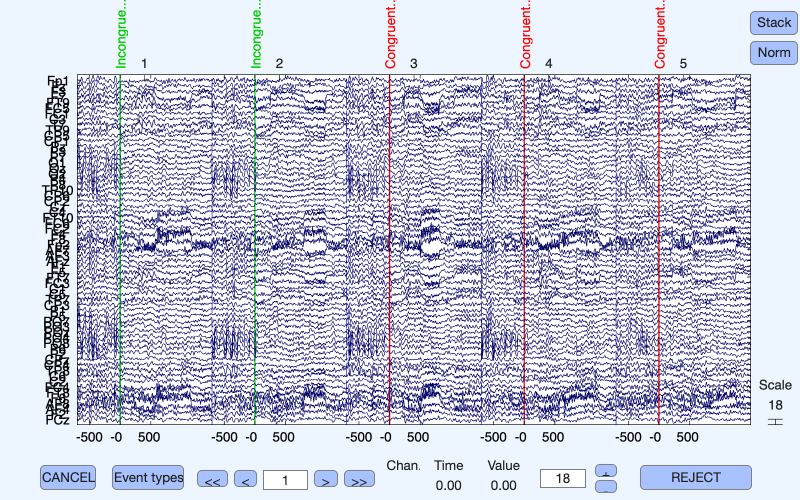


% pop_eegplot(EEG_enc_ep, 1, 1, 1, [], 'title', 'Final Encoding');

% pop_eegplot(EEG_item_ep, 1, 1, 1, [], 'title', 'Final Old/New');
% pop_eegplot(EEG_afc_ep, 1, 1, 1, [], 'title', 'Final 2AFC');